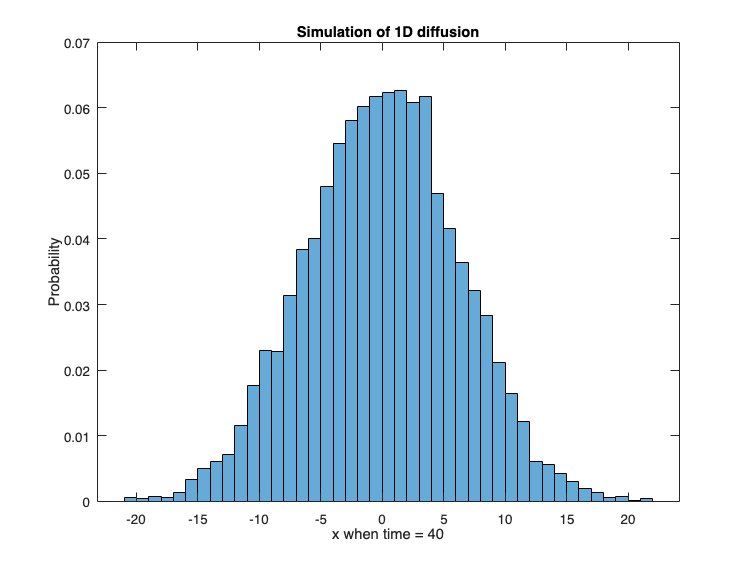

%simulate 1D random walk and get particle’s position at t, repeated many times

n_repetition = 5000; %number of repetitions
numParticles = 1; %one particle
numSteps = 500; %steps per trial
t = 40; %timepoint of interest

for rep = 1:n_repetition
    %initialize position array
    x = zeros(numParticles, numSteps); %start at 0

    %simulate motion
    for stepNumber = 2 : numSteps
        for p = 1 : numParticles
            xStep = randn(); %random step from normal distribution
            x(p, stepNumber) = x(p, stepNumber - 1) + xStep; %update position
        end
    end

    %get x at time t for this trial
    x_t = x(t+1); %indexing offset
    x_ts(rep) = x_t; %store result
end

%plot histogram of all x_t values
figure;
histogram(x_ts, 'Normalization', 'probability');
xlabel(['x when time = ' num2str(t)]);
ylabel('Probability');
title('Simulation of 1D diffusion');